# Designing Luenberger Observer of the system

% Masses are in KG and length in CM.
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 10;

% Substituting given values in the system to check controllability

A = [0 1      0             0      0             0;
     0 0 (-m1*g/M)          0 (-m2*g/M)          0; 
     0 0      0             1      0             0;
     0 0 (-(M+m1)*g)/(M*l1) 0 (-m2*g)/(M*l1)     0;
     0 0      0             0      0             1;
     0 0 -(m1*g)/(M*l2)     0 (-g*(M+m2))/(M*l2) 0]

A =          0    1.0000         0         0         0         0
         0         0   -1.0000         0   -1.0000         0
         0         0         0    1.0000         0         0
         0         0   -0.5500         0   -0.0500         0
         0         0         0         0         0    1.0000
         0         0   -0.1000         0   -1.1000         0



B = [     0; 
        1/M; 
          0; 
    1/(M*(l1)); 
          0; 
    1/(M*l2)]

B = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000



C1 = [1 0 0 0 0 0]                                        

C1 =      1     0     0     0     0     0


C3 = [1 0 0 0 0 0; 0 0 0 0 1 0]             

C3 =      1     0     0     0     0     0
     0     0     0     0     1     0


C4 = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]

C4 =      1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0



% Taking initial Q condition for Luenberger observer
Q = [100  0   0  0  0   0;
         0   80   0  0  0   0;
         0    0 200  0  0   0;
         0    0   0 80  0   0;
         0    0   0  0 50   0;
         0    0   0  0  0 300];
R = 0.0005

R = 5.0000e-04


% Considering initial observer values for later comaprison
X_init = [0.5; 0; 10; 0; 20; 0; 0; 0; 0; 0; 0; 0]

X_init =     0.5000
         0
   10.0000
         0
   20.0000
         0
         0
         0
         0
         0



% Choosing random independent negative eigen values for obeservability
eigen = [-2; -1; -4; -8; -5; -0.5]

eigen =    -2.0000
   -1.0000
   -4.0000
   -8.0000
   -5.0000
   -0.5000



% Observability can be calculated using in-built LQR function.
K = lqr(A,B,Q,R)

K = 1.0e+03 *

    0.4472    1.1258    0.1113   -0.6999    0.2695   -0.2971



% Eigen value placement
L1 = place(A',C1',eigen)'

L1 = 1.0e+03 *

    0.0205
    0.1533
   -0.7707
    0.5094
    0.2620
   -1.1548


L3 = place(A',C3',eigen)'

L3 =    13.7054   -0.7077
   52.6022   -7.6602
  -54.9110   16.1395
    8.4909    4.6821
    0.0499    6.7946
    1.5404    7.5895


L4 = place(A',C4',eigen)'

L4 =     7.0676    2.7807    0.0000
    9.6147   11.6200   -1.0000
    2.7807   10.4324    0.0000
   12.6200   24.3353   -0.0500
    0.0000    0.0000    3.0000
    0.0000   -0.1000    0.9000



% Defining system based on observer C1
A_c1 = [(A-B*K) B*K; zeros(size(A)) (A-L1*C1)]

A_c1 = 1.0e+03 *

         0    0.0010         0         0         0         0         0         0         0         0         0         0
   -0.0004   -0.0011   -0.0011    0.0007   -0.0013    0.0003    0.0004    0.0011    0.0001   -0.0007    0.0003   -0.0003
         0         0         0    0.0010         0         0         0         0         0         0         0         0
   -0.0000   -0.0001   -0.0006    0.0000   -0.0001    0.0000    0.0000    0.0001    0.0000   -0.0000    0.0000   -0.0000
         0         0         0         0         0    0.0010         0         0         0         0         0         0
   -0.0000   -0.0001   -0.0001    0.0001   -0.0011    0.0000    0.0000    0.0001    0.0000   -0.0001    0.0000   -0.0000
         0         0         0         0         0         0   -0.0205    0.0010         0         0         0         0
         0         0         0         0         0         0   -0.1533         0   -0.0010         0   -0.0010         0
         0    

B_c1 = [B; zeros(size(B))]

B_c1 = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000
         0
         0
         0
         0


C_c1 = [C1 zeros(size(C1))]

C_c1 =      1     0     0     0     0     0     0     0     0     0     0     0



% Defining system based on observer C3
A_c3 = [(A-B*K) B*K; zeros(size(A)) (A-L3*C3)]

A_c3 =          0    1.0000         0         0         0         0         0         0         0         0         0         0
   -0.4472   -1.1258   -1.1113    0.6999   -1.2695    0.2971    0.4472    1.1258    0.1113   -0.6999    0.2695   -0.2971
         0         0         0    1.0000         0         0         0         0         0         0         0         0
   -0.0224   -0.0563   -0.5556    0.0350   -0.0635    0.0149    0.0224    0.0563    0.0056   -0.0350    0.0135   -0.0149
         0         0         0         0         0    1.0000         0         0         0         0         0         0
   -0.0447   -0.1126   -0.1111    0.0700   -1.1270    0.0297    0.0447    0.1126    0.0111   -0.0700    0.0270   -0.0297
         0         0         0         0         0         0  -13.7054    1.0000         0         0    0.7077         0
         0         0         0         0         0         0  -52.6022         0   -1.0000         0    6.6602         0
         0         0     

B_c3 = [B; zeros(size(B))]

B_c3 = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000
         0
         0
         0
         0


C_c3 = [C2 zeros(size(C3))]

C_c3 =      0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0



% Defining system based on observer C4
A_c4 = [(A-B*K) B*K; zeros(size(A)) (A-L4*C4)]

A_c4 =          0    1.0000         0         0         0         0         0         0         0         0         0         0
   -0.4472   -1.1258   -1.1113    0.6999   -1.2695    0.2971    0.4472    1.1258    0.1113   -0.6999    0.2695   -0.2971
         0         0         0    1.0000         0         0         0         0         0         0         0         0
   -0.0224   -0.0563   -0.5556    0.0350   -0.0635    0.0149    0.0224    0.0563    0.0056   -0.0350    0.0135   -0.0149
         0         0         0         0         0    1.0000         0         0         0         0         0         0
   -0.0447   -0.1126   -0.1111    0.0700   -1.1270    0.0297    0.0447    0.1126    0.0111   -0.0700    0.0270   -0.0297
         0         0         0         0         0         0   -7.0676    1.0000   -2.7807         0   -0.0000         0
         0         0         0         0         0         0   -9.6147         0  -12.6200         0   -0.0000         0
         0         0     

B_c4 = [B; zeros(size(B))]

B_c4 = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000
         0
         0
         0
         0


C_c4 = [C4 zeros(size(C4))]

C_c4 =      1     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0


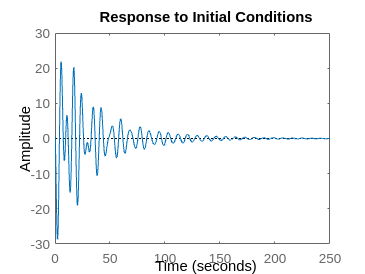


% Calculating state-space based on the system defined by C1
sys_C1 = ss(A_c1, B_c1, C_c1,D);
figure 
initial(sys_C1,X_init)

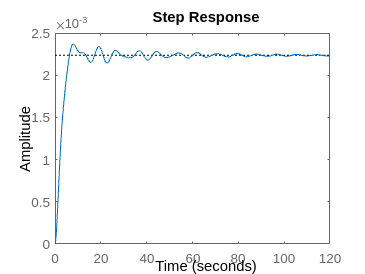

figure
step(sys_C1)

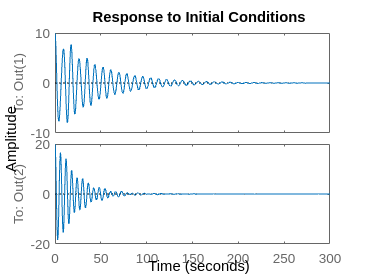


% Calculating state-space based on the system defined by C3
sys_C3 = ss(A_c3, B_c3, C_c3,D);
figure 
initial(sys_C3,X_init)

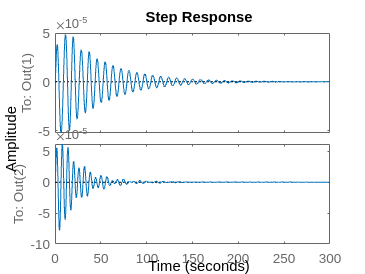

figure
step(sys_C3)

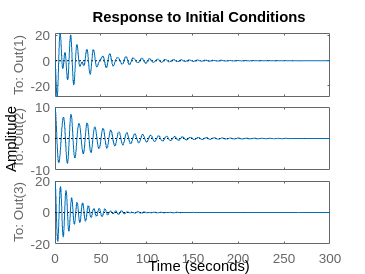


% Calculating state-space based on the system defined by C4
sys_C4 = ss(A_c4, B_c4, C_c4,D);
figure 
initial(sys_C4,X_init)

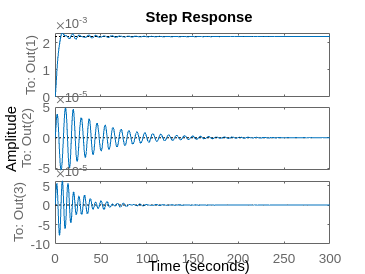

figure
step(sys_C4)